# Regression Assignment Live Script (Part 1 - Grid Partitioning)

### Initialization

clear; clc; close all

## Load, Partition and Normalize Data

data = load('airfoil_self_noise.dat');
[trnData, chkData, tstData] = partition_normalize(data);

## Define Models

#### TSK 1

tsk1_genfisOptions = genfisOptions('GridPartition', ...
                'NumMembershipFunctions', 2, ...
                'InputMembershipFunctionType', 'gbellmf', ...,
                'OutputMembershipFunctionType', 'constant');
tsk1_initFIS = genfis(trnData(:, 1:(end-1)), trnData(:, end), tsk1_genfisOptions);
tsk1_anfisOptions = anfisOptions('InitialFIS', tsk1_initFIS, ...
                'EpochNumber', 300, ...
                'ValidationData', chkData, ...
                'OptimizationMethod', 1);

#### TSK-2

tsk2_genfisOptions = genfisOptions('GridPartition', ...
                'NumMembershipFunctions', 3, ...
                'InputMembershipFunctionType', 'gbellmf', ...,
                'OutputMembershipFunctionType', 'constant');
tsk2_initFIS = genfis(trnData(:, 1:(end-1)), trnData(:, end), tsk2_genfisOptions);
tsk2_anfisOptions = anfisOptions('InitialFIS', tsk2_initFIS, ...
                'EpochNumber', 200, ...
                'ValidationData', chkData, ...
                'OptimizationMethod', 1);
            

#### TSK-3

tsk3_genfisOptions = genfisOptions('GridPartition', ...
                'NumMembershipFunctions', 2, ...
                'InputMembershipFunctionType', 'gbellmf', ...,
                'OutputMembershipFunctionType', 'linear');
tsk3_initFIS = genfis(trnData(:, 1:(end-1)), trnData(:, end), tsk3_genfisOptions);
tsk3_anfisOptions = anfisOptions('InitialFIS', tsk3_initFIS, ...
                'EpochNumber', 300, ...
                'ValidationData', chkData, ...
                'OptimizationMethod', 1);

#### TSK-4

tsk4_genfisOptions = genfisOptions('GridPartition', ...
                'NumMembershipFunctions', 3, ...
                'InputMembershipFunctionType', 'gbellmf', ...,
                'OutputMembershipFunctionType', 'linear');
tsk4_initFIS = genfis(trnData(:, 1:(end-1)), trnData(:, end), tsk4_genfisOptions);
tsk4_anfisOptions = anfisOptions('InitialFIS', tsk4_initFIS, ...
                'EpochNumber', 100, ...
                'ValidationData', chkData, ...
                'OptimizationMethod', 1);

### Train Models

#### Train TSK 1

[tsk1_trnFIS, tsk1_trnError, ~, tsk1_valFIS, tsk1_valError]=anfis(trnData, tsk1_anfisOptions);

ANFIS info:
	Number of nodes: 92
	Number of linear parameters: 32
	Number of nonlinear parameters: 30
	Total number of parameters: 62
	Number of training data pairs: 902
	Number of checking data pairs: 300
	Number of fuzzy rules: 32


Start training ANFIS ...

1 	 4.22356 	 4.82069
2 	 4.19919 	 4.78434
3 	 4.17516 	 4.74844
4 	 4.1515 	 4.71304
Step size increases to 0.011000 after epoch 5.
5 	 4.12824 	 4.67821
6 	 4.1054 	 4.64399
7 	 4.08079 	 4.60712
8 	 4.05675 	 4.57111
Step size increases to 0.012100 after epoch 9.
9 	 4.03332 	 4.53603
10 	 4.01053 	 4.50194
11 	 3.98624 	 4.46565
12 	 3.9628 	 4.43068
Step size increases to 0.013310 after epoch 13.
13 	 3.94024 	 4.39709
14 	 3.9186 	 4.36493
15 	 3.89588 	 4.33123
16 	 3.87433 	 4.29931
Step size increases to 0.014641 after epoch 17.
17 	 3.85396 	 4.26919
18 	 3.83479 	 4.24086
19 	 3.81507 	 4.21175
20 	 3.79679 	 4.18473
Step size increases to 0.016105 after epoch 21.
21 	 3.77991 	 4.15975
22 	 3.76441 	 4.13673
23 	 3.7

#### Train TSK 2

[tsk2_trnFIS, tsk2_trnError, ~, tsk2_valFIS, tsk2_valError]=anfis(trnData, tsk2_anfisOptions);

#### Train TSK 3

[tsk3_trnFIS, tsk3_trnError, ~, tsk3_valFIS, tsk3_valError]=anfis(trnData, tsk3_anfisOptions);

#### Train TSK 4

[tsk4_trnFIS, tsk4_trnError, ~, tsk4_valFIS, tsk4_valError]=anfis(trnData, tsk4_anfisOptions);

## Benchmarking and Graphing

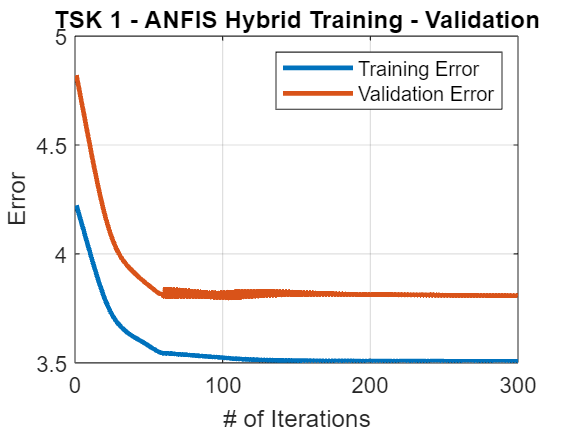

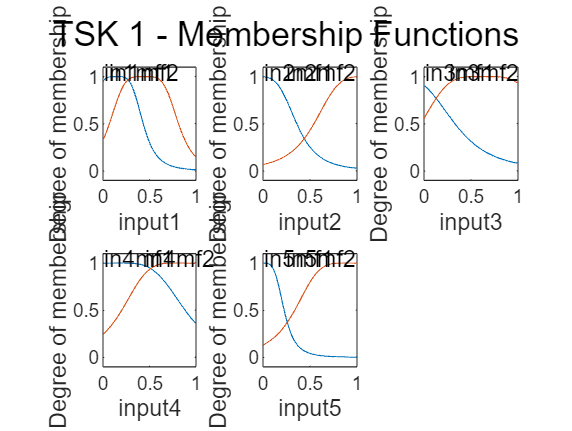

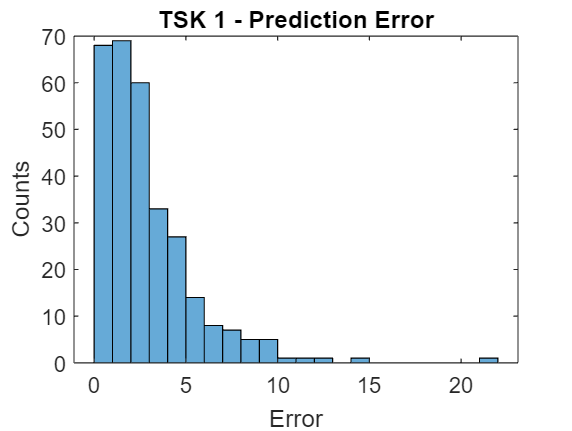

performanceStats = zeros(4,4);

%TSK-1
[RMSE, R2, NMSE, NDEI] = stats_graphs(1, tsk1_valFIS, chkData, tstData, tsk1_trnError, tsk1_valError, 1);

performanceStats(1,:) = [RMSE, R2, NMSE, NDEI];

%TSK-2
[RMSE, R2, NMSE, NDEI] = stats_graphs(2, tsk2_valFIS, chkData, tstData, tsk2_trnError, tsk2_valError, 1);
performanceStats(2,:) = [RMSE, R2, NMSE, NDEI];

%TSK-3
[RMSE, R2, NMSE, NDEI] = stats_graphs(3, tsk3_valFIS, chkData, tstData, tsk3_trnError, tsk3_valError, 1);
performanceStats(3,:) = [RMSE, R2, NMSE, NDEI];

%TSK-4
[RMSE, R2, NMSE, NDEI] = stats_graphs(4, tsk4_valFIS, chkData, tstData, tsk4_trnError, tsk4_valError, 1);
performanceStats(4,:) = [RMSE, R2, NMSE, NDEI];

%% Form Results Table
colNames = {'RMSE','R2','NMSE','NDEI'};
rowNames = {'TSK-1','TSK-2','TSK-3','TSK-4'};
performanceStats = array2table(performanceStats,'VariableNames',colNames,'RowNames',rowNames);